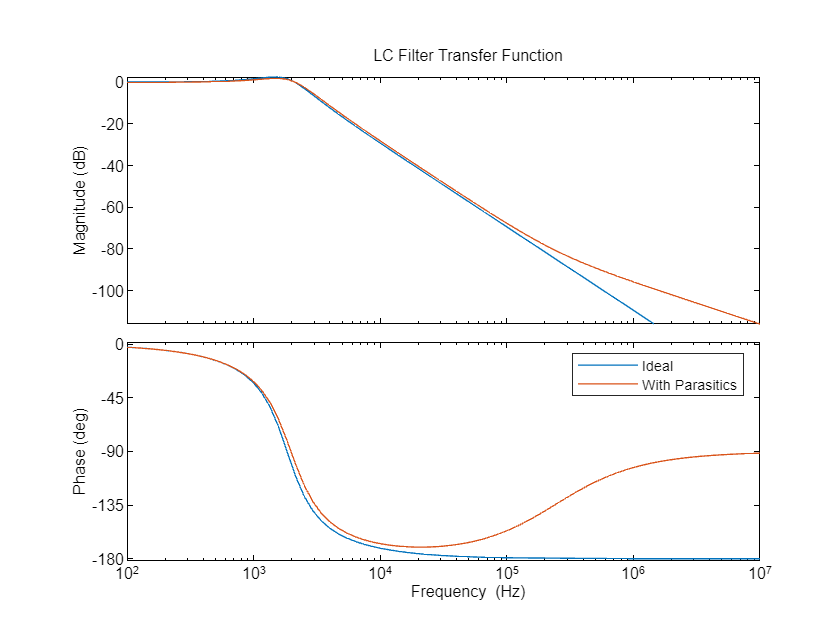

% Written 03/29/2024 By Winnie Szeto for MIT 2.750 Medical Device Design

C = 3 * 22 * 10^-6; % Output Capacitance
R_C = 10 * 10^-3; %Output Cap ESR
L = 100 * 10^-6; %Inductor on Output
R_L = 0.02; %Inductor ESR
Iout = 10;
Vout = 14;
R = Vout / Iout;
Vin = 24;
ModTF = 0.97 * Vin / 3; %PWM goes from 97% to 0% from 0.5V to 3.5V. From 9.3.5 https://www.ti.com/lit/ds/symlink/tl494.pdf

f_LC = 1/(2*pi*sqrt(L*C));

s = tf('s');

LCFilter_Ideal_TF = (R)/(R + L*s+L*R*C*s^2);
LCFilter_Nonideal_TF = (1+C*R_C*s)/(1 + R_L/R + (L/R + R_C*C + R_L*C + (R_L*R_C*C/R))*s + ((R+R_C)/R)*L*C*s^2); %fig 8 https://www.ti.com/lit/an/slva301/slva301.pdf
figure
bode(LCFilter_TF, opts)
hold on
bode(LCFilter_Nonideal_TF, opts);
legend("Ideal", "With Parasitics");
title("LC Filter Transfer Function")

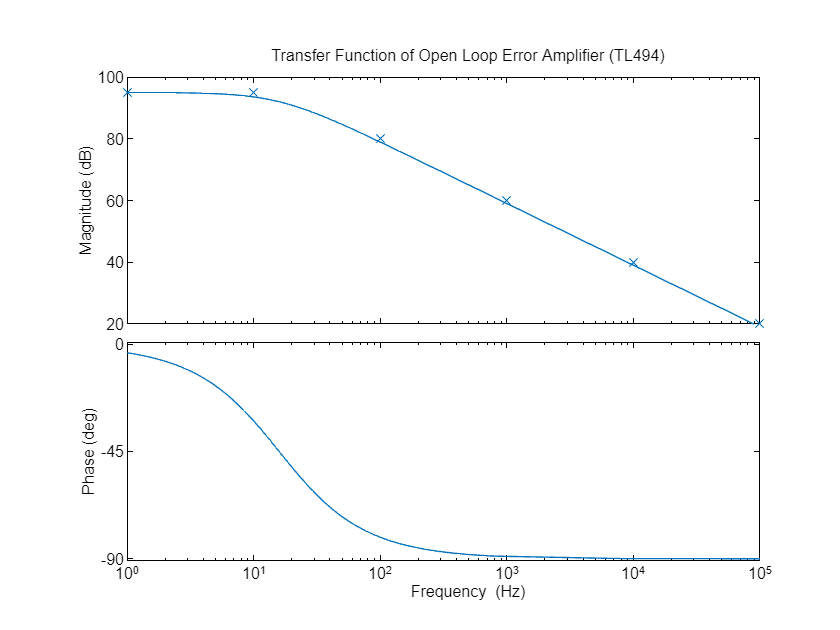


EAFreq = [1 10 1e2 1e3 1e4 1e5];
EAGaindB = [95 95 80 60 40 20];
figure
semilogx(EAFreq, EAGaindB, 'x')
hold on

p_EA = 100;
DCGain_EA = 10^(95/20);
EA_OL_TF = DCGain_EA / (1 + s / p_EA); %from https://www.ti.com/lit/ds/symlink/tl494.pdf

opts = bodeoptions;
opts.FreqUnits = 'Hz';
bode(EA_OL_TF, opts)
xlim([1 10^5])
title("Transfer Function of Open Loop Error Amplifier (TL494)")

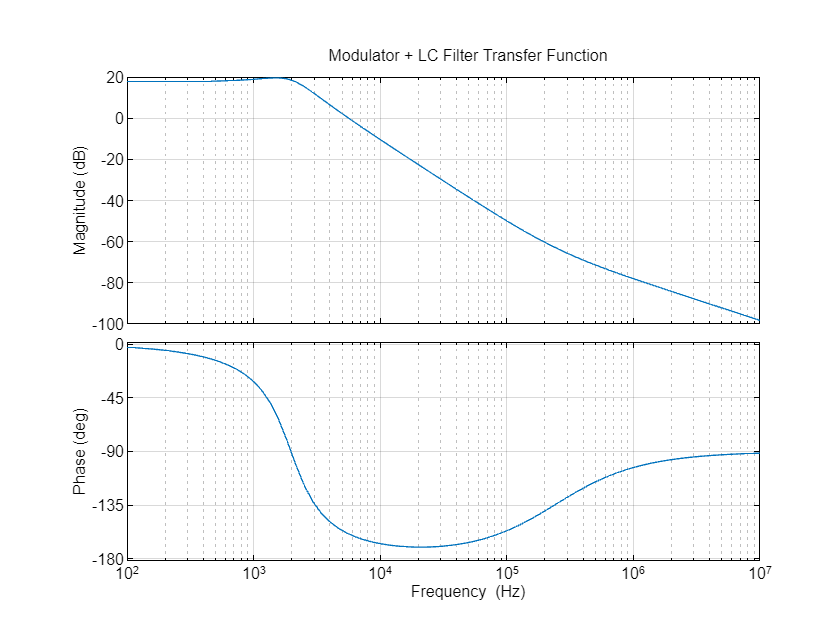


figure
bode(ModTF * LCFilter_Nonideal_TF, opts);
title("Modulator + LC Filter Transfer Function")
grid on


EA_Gain_Crossover = 10^(16/20)

EA_Gain_Crossover = 6.3096


R1 = 100e3;
C3_Suggested = 1/(2*pi*0.9 * f_LC * R1)

C3_Suggested = 9.0267e-10

C3 = 2e-9;
fc = 10000; %crossover Frequency
R3_Suggested = 1/(2*pi*fc*C3)

R3_Suggested = 7.9577e+03

R3 = 8.2e3;
R2_Suggested = 1/(1/R1+1/R3) * EA_Gain_Crossover

R2_Suggested = 4.7817e+04

R2 = 10e3;
C2_Suggested = 1/(1.8*pi*f_LC * R2)

C2_Suggested = 9.0267e-09

C2 = 10e-9;
C1_Suggested = 1/(2*pi*10*fc*R2)

C1_Suggested = 1.5915e-10

C1 = 100e-12;
z1 = 1/(2*pi*C3*R1) %1st zero

z1 = 795.7747

z2 = 1/(2*pi*R2*C2)

z2 = 1.5915e+03

p1 = 1/(2*pi*R3*C3)

p1 = 9.7046e+03

p2 = 1/(2*pi*R2*C1)

p2 = 1.5915e+05

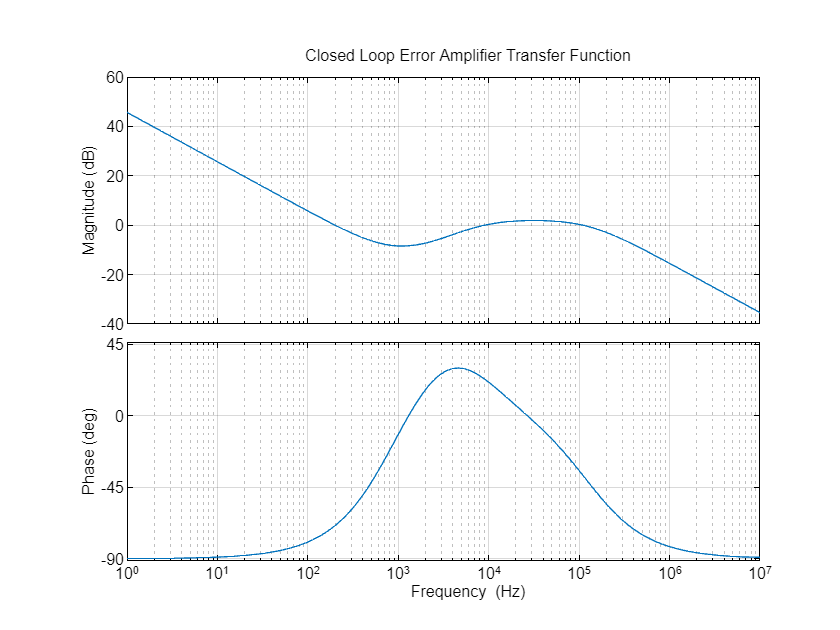

beta = R1*R3*C1*s*(s + (C1+C2)/(C1*C2*R2))*(s + 1/(R2*C3))/((R1+R3)*(s+1/(R2*C2))*(s+1/((R1+R3)*C3))); % from fig 13 https://www.ti.com/lit/an/slva301/slva301.pdf
figure
EA_CL_TF = EA_OL_TF / (1 + EA_OL_TF * beta);
bode(EA_CL_TF, opts);
xlim([1 10^7])
title("Closed Loop Error Amplifier Transfer Function")
grid on

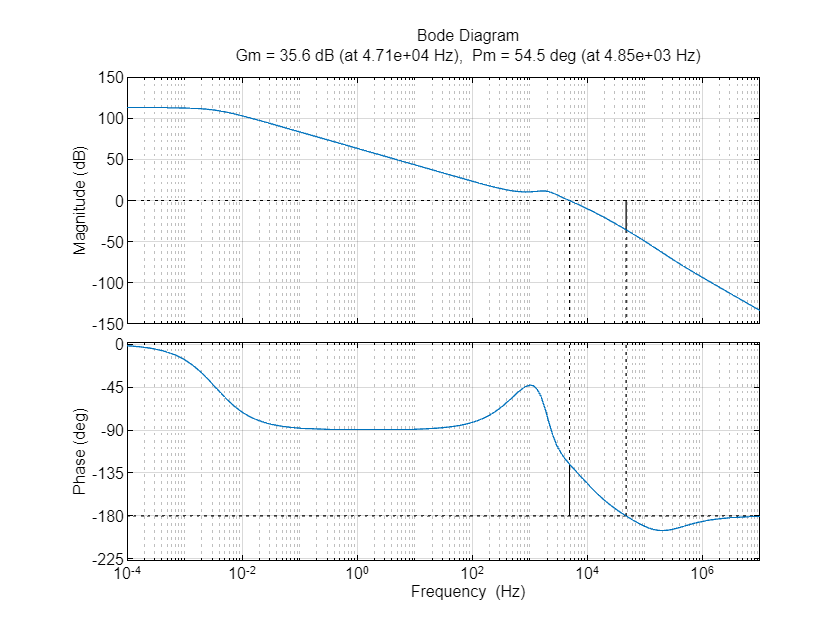


figure
LoopTF = ModTF * LCFilter_Nonideal_TF * EA_CL_TF;
margin(LoopTF, opts);
grid on